# Testing LDE

First, load everything we need...

- Presynaptic neuron # fixed;

- Boundaries tape back

- LGN: Phase variant

- Adding complex cells

CurrentFolder = pwd

CurrentFolder = '/Users/zhuochengxiao/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo082721/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo082121/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

% load('NtWk_Archit.mat')
% E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
% [E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
% E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
% I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
% [I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
% I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);
% 
% N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
% N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_S_HC = 45; n_C_HC = 30; n_I_HC = 31; % per side of HC
N_S = n_S_HC^2 * N_HC^2; % neuron numbers In all
N_C = n_C_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
N_E = N_S+N_C; CplxR = N_C/N_E;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_S = Size_HC/n_S_HC; Size_C = Size_HC/n_C_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnS.X,NnS.Y] = V1Field_Generation(N_HC,1:N_S,'e',n_S_HC,n_I_HC);
[NnC.X,NnC.Y] = V1Field_Generation(N_HC,1:N_C,'e',n_C_HC,n_I_HC);
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');
%NnE.X = [NnS.X,NnC.X]; NnE.Y = [NnS.Y,NnC.Y];

We are fixing boundary effect by connecting neurons to similar ODs

% Extended spatial indexes of E and I neurons (1HC each side)
Nex_S = n_S_HC^2 * (N_HC+2)^2; % neuron numbers In all
Nex_C = n_C_HC^2 * (N_HC+2)^2; 
Nex_I = n_I_HC^2 * (N_HC+2)^2;
[NnSex.X,NnSex.Y] = V1Field_Generation(N_HC+2,1:Nex_S,'e',n_S_HC,n_I_HC);
[NnCex.X,NnCex.Y] = V1Field_Generation(N_HC+2,1:Nex_C,'e',n_C_HC,n_I_HC);
[NnIex.X,NnIex.Y] = V1Field_Generation(N_HC+2,1:Nex_I,'i');

Now select complx cells

N_EE = 193; N_EI = 85; %*0.75
N_IE = 844; N_II = 84; %*0.75 Plan A:Original

CplxNEIncr = 253/N_EE; % Was 250 for 071021 simulation
EcplxInd = ismember(1:N_E, N_S+1:N_E); 

N_SS = N_EE * (1-CplxR);            N_SC = N_EE * (CplxR); 
N_CS = N_EE * (1-CplxR)*CplxNEIncr; N_CC = N_EE * (CplxR)*CplxNEIncr;
N_SI = N_EI;                        N_CI = N_EI; 
N_IS = N_IE * (1-CplxR);            N_IC = N_IE * (CplxR); 

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.530; 
rI_amb = 0.435; % was 0.5 for for 071021 simulation

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.8;  % was 1.6 for for 071021 simulation
S_II = 0.120; S_IE = S_II*0.153 * 1.6/1.8;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
N_Slgn = 4.75; N_Clgn = 1.25; N_Ilgn = 4.5;

lambda_E = 0.02*[N_Slgn*ones(N_S,1);N_Clgn*ones(N_C,1)]; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.02*N_Ilgn; 

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5
%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';

### Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    text = [sprintf('DriveWkSp_Cplx_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    load([DataFolder text],'NWTrace');
    
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    
%     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
%     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
%     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
%     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
    
%     GE_E = [GE_E, GE_ECurrent]; 
%     GE_I = [GE_I, GE_ICurrent];
%     GI_E = [GI_E, GI_ECurrent]; 
%     GI_I = [GI_I, GI_ICurrent];
    
end
load([DataFolder text],'PhaseE');
load( 'DriveWkSp_Cplx_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

### Plot Spatial maps: Plot

WinSize = 9000;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));


Determine On and Off t for Frs and mVs: 

Note, we get rid of the first 10ms of each interval

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
PhaseExc = 20;
mVPh = mod(repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), tMod);
OnOffmV = ~logical(floor(mVPh/MaxOnPhase)); % 1 for all on period, 0 for all off
OnmV  =  OnOffmV & ~(0< mVPh & mVPh<PhaseExc);
OffmV = ~OnOffmV & ~(MaxOnPhase< mVPh & mVPh<MaxOnPhase+PhaseExc);

SpPh = mod(PhaseE(SpE(:,1)) - T + SpE(:,2),tMod);
OnOffSpE =  ~logical(floor(SpPh/MaxOnPhase));
% OnSpE  =  OnOffSpE & ~(0<SpPh & SpPh<PhaseExc);
% OffSpE = ~OnOffSpE & ~(MaxOnPhase<SpPh & SpPh<MaxOnPhase+PhaseExc);
% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

% NnS.X = NnE.X(~EcplxInd); NnS.Y = NnE.Y(~EcplxInd);
% NnC.X = NnE.X(EcplxInd); NnC.Y = NnE.Y(EcplxInd);

FrERan = [0 55];
mVERan = [0.62 0.80];

Figure for ONOFF

First create an onoff vec for each spike

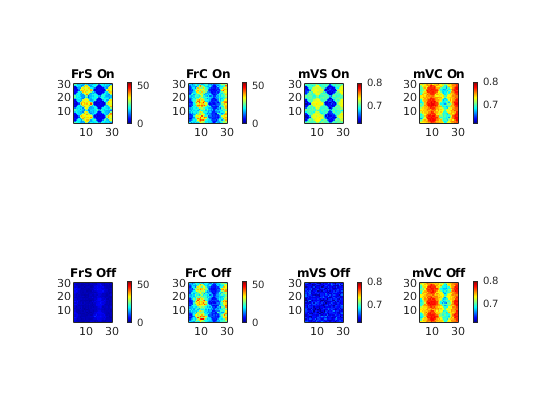

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates:S
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrSOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOnPixMat); title('FrS On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrSOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOffPixMat); title('FrS Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

% Firing rates: C
subplot 242
[FrCOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOnPixMat); title('FrC On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 246
[FrCOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOffPixMat); title('FrC Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% mVs: S
OnmVPhase = double(OnmV);
OnmVPhase(~OnmV) = nan;
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

subplot 243
[mVSOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOnPixMat); title('mVS On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

OffmVPhase = double(OffmV);
OffmVPhase(~OffmV) = nan;
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

subplot 247
[mVSOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOffPixMat); title('mVS Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

% mVs: C
subplot 244
[mVCOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOnPixMat); title('mVC On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

subplot 248
[mVCOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOffPixMat); title('mVC Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

Figure for All Average

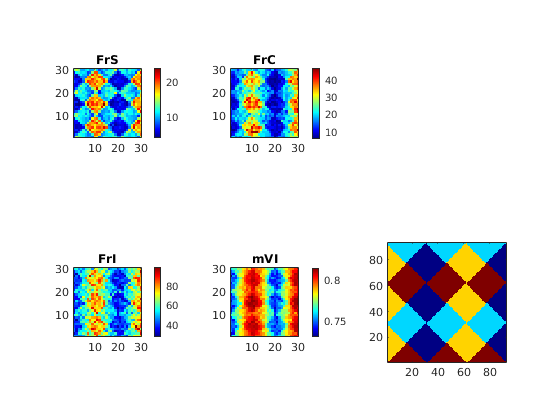

hFrVAll = figure('Name','Field_f&V');
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
%FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

subplot 231
[FrSPixMat,NnSPixel] = NeuVec2Pixel(FrE_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSPixMat); title('FrS')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar
subplot 232
[FrCPixMat,NnCPixel] = NeuVec2Pixel(FrE_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCPixMat); title('FrC')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
% subplot 233
% imagesc(OD_EMap);axis square
% set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

Voltage Traces of S Cells

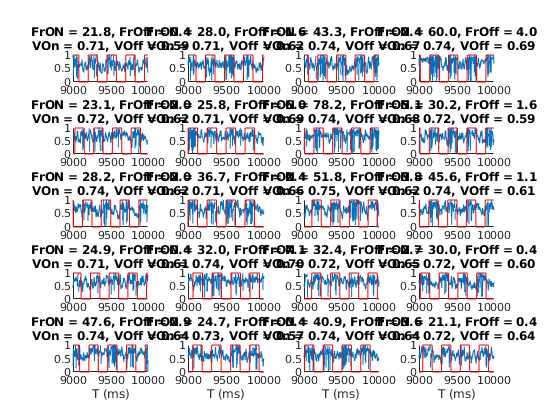

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);
hSpCount = figure('Name','SpCountE');
USE = 1:200:4001;
for subInd = 1:length(USE)-1
    subplot(5,4,subInd)
    NeuInd = OPTS(USE(subInd));
    hold on
    plot(StatWin(1:WinNum),mVE(NeuInd,:))
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-1000 T])
    if ceil(subInd/4) == 5
    xlabel('T (ms)')   
    end
    title(sprintf(['FrON = %.1f, FrOff = %.1f\n',...
                   'VOn = %.2f, VOff = %.2f'],...
                   FrEOn_temp(NeuInd), FrEOff_temp(NeuInd), ...
                   mVEOn_temp(NeuInd), mVEOff_temp(NeuInd)))
       
end

## MF linear equation for pixels: 1 Matrices

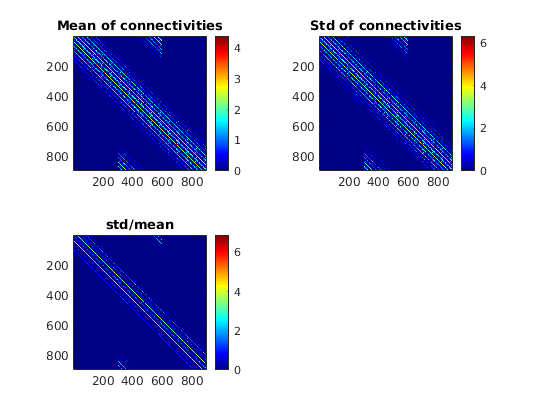

clear ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
      mVE mVEOff mVEOn mVI

load([DataFolder 'ConnPixel_Cconst.mat'])
% Present connectivity mats
figure
subplot 221
imagesc(C_SS_Pixel_Us)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_CS_Pixel_Us)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_CI_Pixel_Us)
axis square
colorbar
title('std/mean')

## Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
      C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
      C_SS_Fix_Bd C_SC_Fix_Bd C_CS_Fix_Bd C_CC_Fix_Bd...
      C_SI_Fix_Bd C_CI_Fix_Bd C_IS_Fix_Bd C_IC_Fix_Bd...
      COpt_Ind SOpt_Ind scatterCOpt scatterSOpt...
      ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
      OffmVPhase OnmVPhase OnOffmV OnOffSpE OnmV OffmV...
      SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood SpPh...
      mVE mVEOff mVEOn mVI ...
      NWTrace AmbE_Events AdjlgnE AmbI_Events CMatAll ...
      EampaInp EnmdaInp GE_ETemp GE_ITemp IampaInp InmdaInp ...
      L6E_Events L6I_Events lgnE_Events lgnI_Events...
      mVECurrent mVICurrent mVETemp mVPh
save('AllMFPixPara_Paper2Tune.mat')   

MF linear equation for pixels: 2 MF Eqns


PixNum = NPixX*N_HC * NPixY*N_HC;
FrSPixVec    = reshape(FrSPixMat,  PixNum,1);
FrSOnPixVec  = reshape(FrSOnPixMat,PixNum,1);
FrSOffPixVec = reshape(FrSOffPixMat,PixNum,1);
FrCPixVec    = reshape(FrCPixMat,  PixNum,1);
FrCOnPixVec  = reshape(FrCOnPixMat,PixNum,1);
FrCOffPixVec = reshape(FrCOffPixMat,PixNum,1);
FrIPixVec    = reshape(FrIPixMat,  PixNum,1);

mVSOnPixVec  = reshape(mVSOnPixMat,PixNum,1);
mVSOffPixVec = reshape(mVSOffPixMat,PixNum,1);
mVCOnPixVec  = reshape(mVCOnPixMat,PixNum,1);
mVCOffPixVec = reshape(mVCOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_SOn_Pixel = zeros(PixNum,1);
lambda_SOff_Pixel = zeros(PixNum,1);
lambda_COn_Pixel = zeros(PixNum,1);
lambda_COff_Pixel = zeros(PixNum,1);
L6S_Pixel = zeros(PixNum,1);
L6C_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
lambda_SOn_drive = lambda_EOn_drive(~EcplxInd); lambda_COn_drive = lambda_EOn_drive(EcplxInd);
lambda_SOff_drive = lambda_EOff_drive(~EcplxInd); lambda_COff_drive = lambda_EOff_drive(EcplxInd);
rS_L6_Drive = rE_L6_Drive(~EcplxInd); rC_L6_Drive = rE_L6_Drive(EcplxInd);
for PixInd = 1:PixNum
    lambda_SOn_Pixel(PixInd)  = mean(lambda_SOn_drive(NnSPixel.Vec == PixInd));
    lambda_SOff_Pixel(PixInd) = mean(lambda_SOff_drive(NnSPixel.Vec == PixInd));
    lambda_COn_Pixel(PixInd)  = mean(lambda_COn_drive(NnCPixel.Vec == PixInd));
    lambda_COff_Pixel(PixInd) = mean(lambda_COff_drive(NnCPixel.Vec == PixInd));
    L6S_Pixel(PixInd) = mean(rS_L6_Drive(NnSPixel.Vec == PixInd));
    L6C_Pixel(PixInd) = mean(rC_L6_Drive(NnCPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive_Pre;

Below need work

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + 2*PixNum;
FrPreUse = FrSOffPixVec(FrPreUseDim - 2*PixNum); 
%FrPreUse = FrEOffLIF(FrPreUseDim - PixNum); 
FrPreUse = [];

MF for all pixels

% Mats
MatSS = (S_EE*(1-p_EEFail))*full(C_SS_Pixel_Us); 
MatSC = (S_EE*(1-p_EEFail))*full(C_SC_Pixel_Us);% Need Ref here??
MatCS = (S_EE*(1-p_EEFail))*full(C_CS_Pixel_Us); 
MatCC = (S_EE*(1-p_EEFail))*full(C_CC_Pixel_Us);% Need Ref here??
MatSI = S_EI *              full(C_SI_Pixel_Us); 
MatCI = S_EI *              full(C_CI_Pixel_Us);
MatIS = S_IE *              full(C_IS_Pixel_Us);
MatIC = S_IE *              full(C_IC_Pixel_Us);
MatII = S_II *              full(C_II_Pixel_Us);
eVSOn  = (Ve-repmat(mVSOnPixVec,1,PixNum));  iVSOn  = (Vi-repmat(mVSOnPixVec,1,PixNum));
eVSOff = (Ve-repmat(mVSOffPixVec,1,PixNum)); iVSOff = (Vi-repmat(mVSOffPixVec,1,PixNum));
eVCOn  = (Ve-repmat(mVCOnPixVec,1,PixNum));  iVCOn  = (Vi-repmat(mVCOnPixVec,1,PixNum));
eVCOff = (Ve-repmat(mVCOffPixVec,1,PixNum)); iVCOff = (Vi-repmat(mVCOffPixVec,1,PixNum));
eVI    = (Ve-repmat(mVIPixVec,1,PixNum));    iVI    = (Vi-repmat(mVIPixVec,1,PixNum));
% post/pre SOn              COn              SOff             COff             I
ConnMat = [MatSS/2.*eVSOn,  MatSC/2.*eVSOn,  MatSS/2.*eVSOn,  MatSC/2.*eVSOn,  MatSI.*iVSOn;  % SOn
           MatCS/2.*eVCOn,  MatCC/2.*eVCOn,  MatCS/2.*eVCOn,  MatCC/2.*eVCOn,  MatCI.*iVCOn;  % COn
           MatSS/2.*eVSOff, MatSC/2.*eVSOff, MatSS/2.*eVSOff, MatSC/2.*eVSOff, MatSI.*iVSOff; % SOff
           MatCS/2.*eVCOff, MatCC/2.*eVCOff, MatCS/2.*eVCOff, MatCC/2.*eVCOff, MatCI.*iVCOff; % COff
           MatIS/2.*eVI,    MatIC/2.*eVI,    MatIS/2.*eVI,    MatIC/2.*eVI,    MatII.*iVI];   % I
% Leak On/Off
LeakSOn  = gL_E * (0-mVSOnPixVec)  * 1e3;
LeakCOn  = gL_E * (0-mVCOnPixVec)  * 1e3;
LeakSOff = gL_E * (0-mVSOffPixVec) * 1e3;
LeakCOff = gL_E * (0-mVCOffPixVec) * 1e3;
LeakI =    gL_I * (0-mVIPixVec)    * 1e3;
LeakV = [LeakSOn;
         LeakCOn;
         LeakSOff;
         LeakCOff;
         LeakI];
% Ext
ExtSOn  = (lambda_SOn_Pixel*S_Elgn  + rE_amb*S_amb + L6S_Pixel*S_EL6).*(Ve-mVSOnPixVec ) * 1e3;
ExtCOn  = (lambda_COn_Pixel*S_Elgn  + rE_amb*S_amb + L6C_Pixel*S_EL6).*(Ve-mVCOnPixVec ) * 1e3;
ExtSOff = (lambda_SOff_Pixel*S_Elgn + rE_amb*S_amb + L6S_Pixel*S_EL6).*(Ve-mVSOffPixVec) * 1e3;
ExtCOff = (lambda_COff_Pixel*S_Elgn + rE_amb*S_amb + L6C_Pixel*S_EL6).*(Ve-mVCOffPixVec) * 1e3;
ExtI =    (lambda_I_Pixel*S_Ilgn    + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec)    * 1e3;
ExtV = [ExtSOn;
        ExtCOn;
        ExtSOff;
        ExtCOff
        ExtI];
% Ref Vec
RefSOn = 1-FrSOnPixVec*tau_ref/1e3;
RefCOn = 1-FrCOnPixVec*tau_ref/1e3;
RefSOff = 1-FrSOffPixVec*tau_ref/1e3;
RefCOff = 1-FrCOffPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = diag([RefSOn;...
             RefCOn;...
             RefSOff;...
             RefCOff;...
             RefI]);
% L4 Frs
Fr_L4 = [FrSOnPixVec; FrCOnPixVec; FrSOffPixVec; FrCOffPixVec; FrIPixVec];

% MF Equations:
Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
tic
    if isempty(FrPreUse)
    Fr_MFinv = (sparse(eye(5*PixNum))-RefM*ConnMat) \ (RefM * ( ExtV + LeakV));
    else
        FrPreVec = zeros(PixNum*5,1); FrPreVec(FrPreUseDim) = FrPreUse;
        DimAll = 1:PixNum*5; FrminusDim = DimAll(~ismember(DimAll,FrPreUseDim));
        FrPreReplace = RefM*ConnMat * FrPreVec; 
        % Now compute in the subspace
        FrPreMinus = FrPreReplace(FrminusDim);
        RefMMinus  = RefM(FrminusDim, FrminusDim);
        ConnMatMinus = ConnMat(FrminusDim, FrminusDim);
        ExtVMinus = ExtV(FrminusDim);
        LeakVMinus = LeakV(FrminusDim);
        Fr_MFinvMinus = (sparse(eye(length(FrminusDim)))-RefMMinus*ConnMatMinus) \ ...
                        (RefMMinus * ( ExtVMinus + LeakVMinus) + FrPreMinus);
        % make up MF output            
        Fr_MFinv = zeros(PixNum*5,1);   
        Fr_MFinv(FrminusDim) = Fr_MFinvMinus; Fr_MFinv(FrPreUseDim) = FrPreUse; 
    end
toc

Elapsed time is 0.836606 seconds.


% Err
FrErr = Fr_MFinv - Fr_L4;

## Select one pixel, do LDE

PX = 20; PY = 25; %OPT
%PX = 20; PY = 25; %ORT
%PX = 9; PY = 9; %ORT
PInd = (PX-1)*N_HC*NPixY + PY;
VSonP = mVSOnPixVec(PInd); VSoffP = mVSOffPixVec(PInd);
VConP = mVCOnPixVec(PInd); VCoffP = mVCOffPixVec(PInd);
VIP   = mVIPixVec(PInd);
meanVs = [VSonP;VConP;VSoffP;VCoffP;VIP]

meanVs =     0.6435
    0.6810
    0.6410
    0.6802
    0.7416


f_pre = [FrSOnPixVec(PInd) ;
         FrCOnPixVec(PInd); 
         FrSOffPixVec(PInd);
         FrCOffPixVec(PInd);
         FrIPixVec(PInd)]

f_pre =     6.5556
    6.6667
    6.3556
    5.4321
   36.0278


% Input
NlgnS = N_Slgn; NlgnC = N_Clgn; NlgnI = N_Ilgn;
rL6E = (L6S_Pixel(PInd) + L6S_Pixel(PInd))/2; rL6I = L6I_Pixel(PInd);
lgn_SOnOff = [lambda_SOn_Pixel(PInd)/NlgnS ;
              lambda_SOff_Pixel(PInd)/NlgnS]; 
lgn_COnOff = [ lambda_COn_Pixel(PInd)/NlgnC;
              lambda_COff_Pixel(PInd)/NlgnC]; 
lgn_I = lambda_I_Pixel/NlgnI;
% L4 Input and parameters
N_PreSynPix(1,1) = C_SS_Pixel_Us(PInd, PInd);%mean(diag(C_SS_Pixel_Us)); %; 
N_PreSynPix(1,2) = C_CS_Pixel_Us(PInd, PInd);%mean(diag(C_CS_Pixel_Us)); %;
N_PreSynPix(1,3) = C_IS_Pixel_Us(PInd, PInd);%mean(diag(C_IS_Pixel_Us)); %;
N_PreSynPix(2,1) = C_SC_Pixel_Us(PInd, PInd);%mean(diag(C_SC_Pixel_Us)); %;
N_PreSynPix(2,2) = C_CC_Pixel_Us(PInd, PInd);%mean(diag(C_CC_Pixel_Us)); %;
N_PreSynPix(2,3) = C_IC_Pixel_Us(PInd, PInd);%mean(diag(C_IC_Pixel_Us)); %;
N_PreSynPix(3,1) = C_SI_Pixel_Us(PInd, PInd);%mean(diag(C_SI_Pixel_Us)); %;
N_PreSynPix(3,2) = C_CI_Pixel_Us(PInd, PInd);%mean(diag(C_CI_Pixel_Us)); %;
N_PreSynPix(3,3) = C_II_Pixel_Us(PInd, PInd);%mean(diag(C_II_Pixel_Us)); %;

L4SE = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
      - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4SI = C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4CE = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
      - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4CI = C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4IE = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
      - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4II = C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);

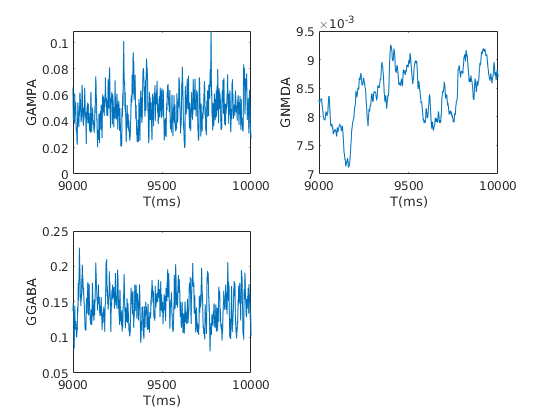

mVLIF =     0.6398
    0.6802
    0.6378
    0.6933
    0.7422


FrLIF = 5×1 single column vector
    6.5263
    9.0526
    7.4737
    9.2632
   44.3158


LIFSimuT = 10000;
Fr_MFinv = f_pre;
tic
[mVLIF,FrLIF] = LIF1Pixel(Fr_MFinv, N_PreSynPix, L4SE,L4SI, L4CE,L4CI, L4IE,L4II,...
                                 S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                 S_EL6,S_IL6,rL6E,rL6I,S_amb,rE_amb,rI_amb,...%7 L6 Amb                                   
                                 lgn_SOnOff,lgn_COnOff,lgn_I,NlgnS,NlgnC,NlgnI, S_Elgn,S_Ilgn,...
                                 tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                 rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                 gL_E,gL_I,Ve,Vi,LIFSimuT, dt)

toc% No more Freq

Elapsed time is 0.720193 seconds.



HyperPara = {'Traj',50,50,1,5000};
tic
[f_EnIOut,meanVs,loop,SteadyIndicate,FailureIndicate]...
           = MFpV_SinglePixel(...
...% MF Parameters                     
                     N_PreSynPix, L4SE,L4SI, L4CE,L4CI, L4IE,L4II,... %3 
                     S_EE,S_EI,S_IE,S_II,p_EEFail,... %5
                     S_EL6,S_IL6,rL6E,rL6I,S_amb,rE_amb,rI_amb,...%7 L6 Amb                                   
                     lgn_SOnOff, lgn_COnOff,lgn_I,NlgnS,NlgnC,NlgnI, S_Elgn,S_Ilgn,... %7
                     gL_E,gL_I,Ve,Vi, tau_ref,... %5
...% Below are LIF details
                     tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,... %7
                     rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,... %4
                     HyperPara);

Firing rates unconverged


toc

Elapsed time is 13.780165 seconds.


mean(f_EnIOut(:,end-25:end),2)

ans =     6.2511
   10.0748
    6.3633
   10.1629
   47.6409


## LIF only

tic
[f_EnIOut,loop,SteadyIndicate,FailureIndicate]...
           = MF_free_LIF_SinglePixel(...
...% MF Parameters                     
                     N_PreSynPix, L4SE,L4SI, L4CE,L4CI, L4IE,L4II,... %3 
                     S_EE,S_EI,S_IE,S_II,p_EEFail,... %5
                     S_EL6,S_IL6,rL6E,rL6I,S_amb,rE_amb,rI_amb,...%7 L6 Amb                                   
                     lgn_EOnOff,lgn_I,NlgnS,NlgnC,NlgnI, S_Elgn,S_Ilgn,... %7
                     gL_E,gL_I,Ve,Vi, tau_ref,... %5
...% Below are LIF details
                     tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,... %7
                     rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,... %4
                     HyperPara);
toc

## Inputs for all pixels

and direct MF for vs

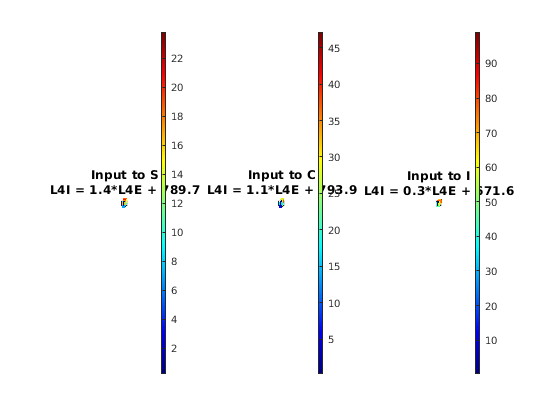

L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
mVMF = zeros(5,PixNum);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
%PX = 20; PY = 25; %ORT
%PX = 9; PY = 9; %ORT
VSonP = mVSOnPixVec(PInd); VSoffP = mVSOffPixVec(PInd);
VConP = mVCOnPixVec(PInd); VCoffP = mVCOffPixVec(PInd);
VIP   = mVIPixVec(PInd);
meanVs = [VSonP;VConP;VSoffP;VCoffP;VIP];
f_pre = [FrSOnPixVec(PInd) ;
         FrCOnPixVec(PInd); 
         FrSOffPixVec(PInd);
         FrCOffPixVec(PInd);
         FrIPixVec(PInd)];
% Input
NlgnS = N_Slgn; NlgnC = N_Clgn; NlgnI = N_Ilgn;
rL6E = (L6S_Pixel(PInd) + L6S_Pixel(PInd))/2; rL6I = L6I_Pixel(PInd);
lgn_SOnOff = [lambda_SOn_Pixel(PInd)/NlgnS ;
              lambda_SOff_Pixel(PInd)/NlgnS]; 
lgn_COnOff = [ lambda_COn_Pixel(PInd)/NlgnC;
              lambda_COff_Pixel(PInd)/NlgnC]; 
lgn_I = lambda_I_Pixel/NlgnI;
% L4 Input and parameters
N_PreSynPix(1,1) = C_SS_Pixel_Us(PInd, PInd);%mean(diag(C_SS_Pixel_Us)); %; 
N_PreSynPix(1,2) = C_CS_Pixel_Us(PInd, PInd);%mean(diag(C_CS_Pixel_Us)); %;
N_PreSynPix(1,3) = C_IS_Pixel_Us(PInd, PInd);%mean(diag(C_IS_Pixel_Us)); %;
N_PreSynPix(2,1) = C_SC_Pixel_Us(PInd, PInd);%mean(diag(C_SC_Pixel_Us)); %;
N_PreSynPix(2,2) = C_CC_Pixel_Us(PInd, PInd);%mean(diag(C_CC_Pixel_Us)); %;
N_PreSynPix(2,3) = C_IC_Pixel_Us(PInd, PInd);%mean(diag(C_IC_Pixel_Us)); %;
N_PreSynPix(3,1) = C_SI_Pixel_Us(PInd, PInd);%mean(diag(C_SI_Pixel_Us)); %;
N_PreSynPix(3,2) = C_CI_Pixel_Us(PInd, PInd);%mean(diag(C_CI_Pixel_Us)); %;
N_PreSynPix(3,3) = C_II_Pixel_Us(PInd, PInd);%mean(diag(C_II_Pixel_Us)); %;

L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4SI(PInd) = C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4CI(PInd) = C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4II(PInd) = C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);

N_SSi = N_PreSynPix(1,1); N_CSi = N_PreSynPix(1,2); N_ISi = N_PreSynPix(1,3); %% REally?? Row/Col
N_SCi = N_PreSynPix(2,1); N_CCi = N_PreSynPix(2,2); N_ICi = N_PreSynPix(2,3); 
N_SIi = N_PreSynPix(3,1); N_CIi = N_PreSynPix(3,2); N_IIi = N_PreSynPix(3,3); 

% Prepare This pixel connectivity
MatSS = (S_EE*(1-p_EEFail))*N_SSi; MatCS = (S_EE*(1-p_EEFail))*N_CSi; MatIS = S_IE * N_ISi;
MatSC = (S_EE*(1-p_EEFail))*N_SCi; MatCC = (S_EE*(1-p_EEFail))*N_CCi; MatIC = S_IE * N_ICi;
MatSI = S_EI *              N_SIi; MatCI = S_EI *              N_CIi; MatII = S_II * N_IIi;

ConnMat_VFac = ... % Factor of meanVs
    [MatSS/2, MatSC/2, MatSS/2, MatSC/2, MatSI;  % SOn
     MatCS/2, MatCC/2, MatCS/2, MatCC/2, MatCI;  % COn
     MatSS/2, MatSC/2, MatSS/2, MatSC/2, MatSI;  % SOff
     MatCS/2, MatCC/2, MatCS/2, MatCC/2, MatCI;  % COff
     MatIS/2, MatIC/2, MatIS/2, MatIC/2, MatII]; % I
ConnMat_RevV = ...% Net current from reversal potentials
    [MatSS/2*Ve, MatSC/2*Ve, MatSS/2*Ve, MatSC/2*Ve, MatSI*Vi;  % SOn
     MatCS/2*Ve, MatCC/2*Ve, MatCS/2*Ve, MatCC/2*Ve, MatCI*Vi;  % COn
     MatSS/2*Ve, MatSC/2*Ve, MatSS/2*Ve, MatSC/2*Ve, MatSI*Vi;  % SOff
     MatCS/2*Ve, MatCC/2*Ve, MatCS/2*Ve, MatCC/2*Ve, MatCI*Vi;  % COff
     MatIS/2*Ve, MatIC/2*Ve, MatIS/2*Ve, MatIC/2*Ve, MatII*Vi]; % I
LeakV_VFac = [gL_E*ones(4,1);gL_I]*1e3;
% Ext input to this pixel
ExtSOn_VFac  = (lgn_SOnOff(1)*NlgnS*S_Elgn + rE_amb*S_amb + rL6E*S_EL6) *1e3 ...
             + (L4SI(PInd)*S_EI) + L4SE(PInd)*S_EE*(1-p_EEFail); 
ExtCOn_VFac  = (lgn_COnOff(1)*NlgnC*S_Elgn + rE_amb*S_amb + rL6E*S_EL6) *1e3 ...
             + (L4CI(PInd)*S_EI) + L4CE(PInd)*S_EE*(1-p_EEFail);
ExtSOff_VFac = (lgn_SOnOff(2)*NlgnS*S_Elgn + rE_amb*S_amb + rL6E*S_EL6) *1e3...
             + (L4SI(PInd)*S_EI) + L4SE(PInd)*S_EE*(1-p_EEFail);
ExtCOff_VFac = (lgn_COnOff(2)*NlgnC*S_Elgn + rE_amb*S_amb + rL6E*S_EL6) *1e3...
             + (L4CI(PInd)*S_EI) + L4CE(PInd)*S_EE*(1-p_EEFail);
ExtI_VFac =    (lgn_I        *NlgnI*S_Ilgn + rI_amb*S_amb + rL6I*S_IL6) *1e3...
             + (L4II(PInd)*S_II) + L4IE(PInd)*S_IE;
ExtV_VFac = [ExtSOn_VFac;
             ExtCOn_VFac;
             ExtSOff_VFac;
             ExtCOff_VFac;
             ExtI_VFac];

ExtSOn_RevV  = (lgn_SOnOff(1)*NlgnS*S_Elgn + rE_amb*S_amb + rL6E*S_EL6)*Ve *1e3 ...
             + (L4SI(PInd)*S_EI)*Vi + L4SE(PInd)*S_EE*Ve*(1-p_EEFail); 
ExtCOn_RevV  = (lgn_COnOff(1)*NlgnC*S_Elgn + rE_amb*S_amb + rL6E*S_EL6)*Ve *1e3 ...
             + (L4CI(PInd)*S_EI)*Vi + L4CE(PInd)*S_EE*Ve*(1-p_EEFail);
ExtSOff_RevV = (lgn_SOnOff(2)*NlgnS*S_Elgn + rE_amb*S_amb + rL6E*S_EL6)*Ve *1e3...
             + (L4SI(PInd)*S_EI)*Vi + L4SE(PInd)*S_EE*Ve*(1-p_EEFail);
ExtCOff_RevV = (lgn_COnOff(2)*NlgnC*S_Elgn + rE_amb*S_amb + rL6E*S_EL6)*Ve *1e3...
             + (L4CI(PInd)*S_EI)*Vi + L4CE(PInd)*S_EE*Ve*(1-p_EEFail);
ExtI_RevV =    (lgn_I        *NlgnI*S_Ilgn + rI_amb*S_amb + rL6I*S_IL6)*Ve *1e3...
             + (L4II(PInd)*S_II)*Vi + L4IE(PInd)*S_IE*Ve;
ExtV_RevV = [ExtSOn_RevV;
             ExtCOn_RevV;
             ExtSOff_RevV;
             ExtCOff_RevV;
             ExtI_RevV];

% New equip
NetInp = f_pre./(1-tau_ref*f_pre/1000);
RevV_All = ConnMat_RevV*f_pre + ExtV_RevV;
VFac_All = sum(ConnMat_VFac,2) + ExtV_VFac + LeakV_VFac;
mVMF(:,PInd) = (RevV_All - NetInp)./VFac_All;
end

figure('Name','L4 Inputs')
subplot 131
hold on
scatter3(L4SE(:),L4SI(:), lambda_SOn_Pixel,[],FrSPixVec,'.')
P1 = polyfit(L4SE(:),L4SI(:),1);
[x,z] = meshgrid(linspace(min(L4SE),max(L4SE),10),...
                 linspace(min(lambda_SOn_Pixel),max(lambda_SOn_Pixel),10));
yfit = P1(1)*x + P1(2);
mesh(x,yfit,z,'FaceAlpha',0.5); shading flat
axis square;grid on
xlabel('L4E to S'); ylabel('L4I to S');zlabel('LGN to Son'); 
title({'Input to S',sprintf('L4I = %.1f*L4E + %.1f',P1(1),P1(2))})
colorbar; colormap jet
view(-25, 15)

subplot 132
hold on
scatter3(L4CE(:),L4CI(:), lambda_SOn_Pixel,[],FrCPixVec,'.')
P2 = polyfit(L4CE(:),L4CI(:),1);
[x,z] = meshgrid(linspace(min(L4CE),max(L4CE),10),...
                 linspace(min(lambda_SOn_Pixel),max(lambda_SOn_Pixel),10));
yfit = P2(1)*x + P2(2);
mesh(x,yfit,z,'FaceAlpha',0.5); shading flat
axis square;grid on
xlabel('L4E to C'); ylabel('L4I to C'); 
title({'Input to C',sprintf('L4I = %.1f*L4E + %.1f',P2(1),P2(2))})
colorbar; colormap jet
view(-25, 15)

subplot 133
hold on
scatter3(L4IE(:),L4II(:), lambda_SOn_Pixel,[],FrIPixVec,'.')
P3 = polyfit(L4IE(:),L4II(:),1);
[x,z] = meshgrid(linspace(min(L4IE),max(L4IE),10),...
                 linspace(min(lambda_SOn_Pixel),max(lambda_SOn_Pixel),10));
yfit = P3(1)*x + P3(2);
mesh(x,yfit,z,'FaceAlpha',0.5); shading flat
axis square;grid on
xlabel('L4E to I'); ylabel('L4I to I'); 
title({'Input to I',sprintf('L4I = %.1f*L4E + %.1f',P3(1),P3(2))})
colorbar; colormap jet
view(-25, 15)

Fix Frs, Check MF mVs

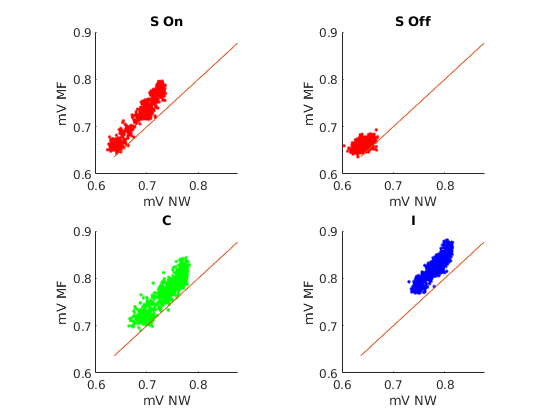

figure('Name','MF mVs')
DiagPlot = min(mVMF,[],'all'): 0.01: max(mVMF,[],'all');
subplot 221
hold on
scatter(mVSOnPixVec,mVMF(1,:)','r.')
plot(DiagPlot,DiagPlot)
xlabel('mV NW'); ylabel('mV MF'); title('S On')
axis square

subplot 222
hold on
scatter(mVSOffPixVec,mVMF(3,:)','r.')
plot(DiagPlot,DiagPlot)
xlabel('mV NW'); ylabel('mV MF'); title('S Off')
axis square

subplot 223
hold on
scatter((mVCOnPixVec+mVCOnPixVec)/2,(mVMF(2,:)+mVMF(4,:))/2','g.')
plot(DiagPlot,DiagPlot)
xlabel('mV NW'); ylabel('mV MF'); title('C')
axis square

subplot 224
hold on
scatter(mVIPixVec,mVMF(5,:)','b.')
plot(DiagPlot,DiagPlot)
xlabel('mV NW'); ylabel('mV MF'); title('I')
axis square

## MF+V results

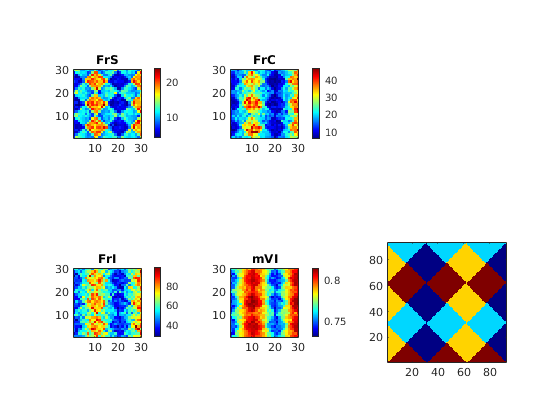

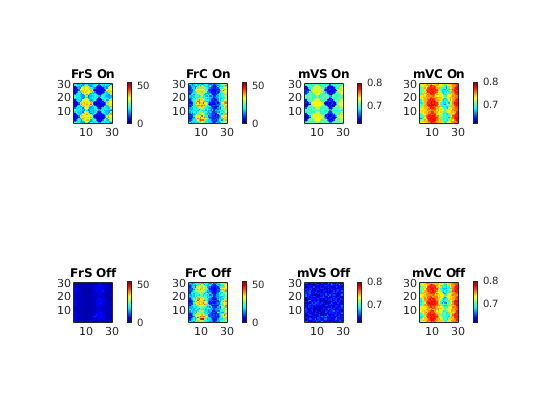

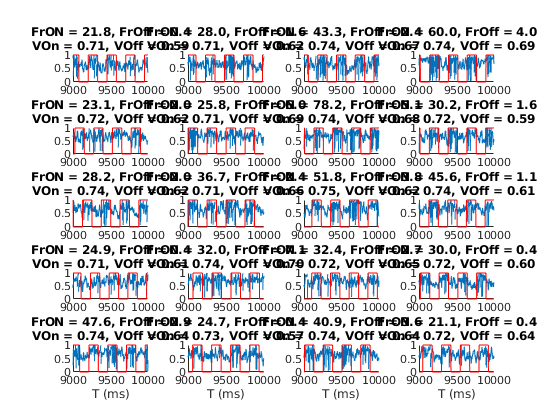

load('AllMFPixPara.mat')

%load('MFpVPix_New.mat')

%load('MFpVPix_New.mat')
%load('MFpVPixdelay0.5.mat')
load('MFpVPixthre0.2.mat')
%load('MFpVPixVth0.2.mat')
% Compute averaged results
PixNum = 900;
FrMFpV = zeros(5,PixNum);
mVMFpV = zeros(5,PixNum);
for PixInd = 1:PixNum
    FrMFpV(:,PixInd) = mean(f_EnIOut{PixInd}(:,end-25:end),2);
    mVMFpV(:,PixInd) = mean(meanVs{PixInd}(:,end-25:end),2);
end
FrSMFV = ((FrMFpV(1,:) + FrMFpV(3,:))/2)';
FrCMFV = ((FrMFpV(2,:) + FrMFpV(4,:))/2)';
FrIMFV = (FrMFpV(5,:))';
%mVSMFV = ((mVMFpV(1,:) + mVMFpV(3,:))/2)';
mVCMFV = ((mVMFpV(2,:) + mVMFpV(4,:))/2)';
mVIMFV = (mVMFpV(5,:))';

figure('Name','Comparison')
subplot 241
hold on
scatter(FrSPixVec,FrSMFV,'r.')
plot(0:35,0:35)
xlabel('FrS On NW');ylabel('FrS On MF+V')


subplot 243
hold on
scatter(FrCPixVec,FrCMFV,'g.')
plot(0:47,0:47)
xlabel('FrC NW');ylabel('FrC MF+V')

subplot 244
hold on
scatter(FrIPixVec,FrIMFV,'b.')
plot(0:100,0:100)
xlabel('FrI NW');ylabel('FrI MF+V')

subplot 245
hold on
scatter(mVSOnPixVec,mVMFpV(1,:),'r.')
plot(0.6:0.1:0.8,0.6:0.1:0.8)
xlabel('mVS On NW');ylabel('mVS On MF+V')

subplot 246
hold on
scatter(mVSOffPixVec,mVMFpV(2,:),'r.')
plot(0.6:0.1:0.8,0.6:0.1:0.8)
xlabel('mVS Off NW');ylabel('mVS Off MF+V')

subplot 247
hold on
scatter((mVCOnPixVec+mVCOffPixVec)/2,mVCMFV,'g.')
plot(0.6:0.1:0.8,0.6:0.1:0.8)
xlabel('mVC NW');ylabel('mVC MF+V')

subplot 248
hold on
scatter(mVIPixVec,mVIMFV,'b.')
plot(0.6:0.1:0.8,0.6:0.1:0.8)
xlabel('mVI NW');ylabel('mVI MF+V')

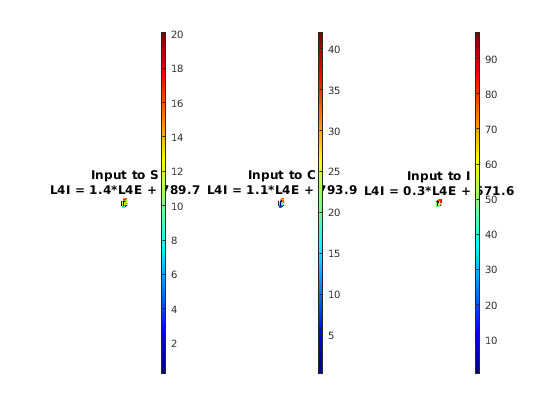

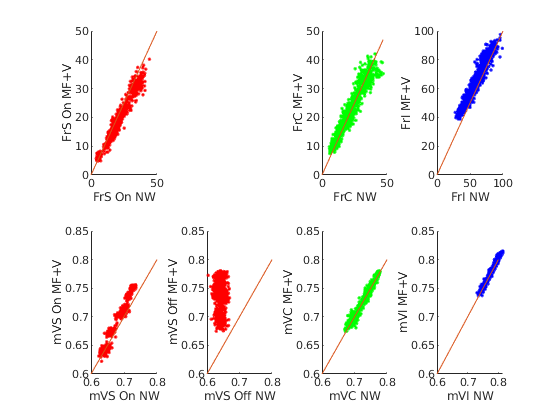

figure('Name','L4 Inputs')
subplot 131
hold on
scatter3(L4SE(:),L4SI(:), lambda_SOn_Pixel,[],FrSMFV,'.')
P1 = polyfit(L4SE(:),L4SI(:),1);
[x,z] = meshgrid(linspace(min(L4SE),max(L4SE),10),...
                 linspace(min(lambda_SOn_Pixel),max(lambda_SOn_Pixel),10));
yfit = P1(1)*x + P1(2);
mesh(x,yfit,z,'FaceAlpha',0.5); shading flat
axis square;grid on
xlabel('L4E to S'); ylabel('L4I to S');zlabel('LGN to Son'); 
title({'Input to S',sprintf('L4I = %.1f*L4E + %.1f',P1(1),P1(2))})
colorbar; colormap jet
view(-25, 15)

subplot 132
hold on
scatter3(L4CE(:),L4CI(:), lambda_SOn_Pixel,[],FrCMFV,'.')
P2 = polyfit(L4CE(:),L4CI(:),1);
[x,z] = meshgrid(linspace(min(L4CE),max(L4CE),10),...
                 linspace(min(lambda_SOn_Pixel),max(lambda_SOn_Pixel),10));
yfit = P2(1)*x + P2(2);
mesh(x,yfit,z,'FaceAlpha',0.5); shading flat
axis square;grid on
xlabel('L4E to C'); ylabel('L4I to C'); 
title({'Input to C',sprintf('L4I = %.1f*L4E + %.1f',P2(1),P2(2))})
colorbar; colormap jet
view(-25, 15)

subplot 133
hold on
scatter3(L4IE(:),L4II(:), lambda_SOn_Pixel,[],FrIMFV,'.')
P3 = polyfit(L4IE(:),L4II(:),1);
[x,z] = meshgrid(linspace(min(L4IE),max(L4IE),10),...
                 linspace(min(lambda_SOn_Pixel),max(lambda_SOn_Pixel),10));
yfit = P3(1)*x + P3(2);
mesh(x,yfit,z,'FaceAlpha',0.5); shading flat
axis square;grid on
xlabel('L4E to I'); ylabel('L4I to I'); 
title({'Input to I',sprintf('L4I = %.1f*L4E + %.1f',P3(1),P3(2))})
colorbar; colormap jet
view(-25, 15)

## LDE firing rate functions

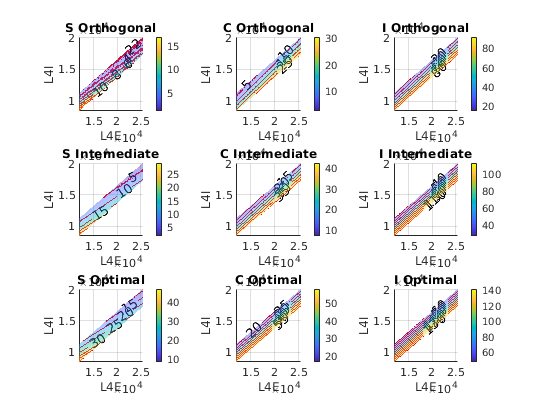


% Determine L4 Input from a range
L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
for PInd = 1:N_HC*NPixX*N_HC*NPixY
L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
            - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
end
L4Eall = L4SE+L4CE+L4IE; L4Iall = L4SI+L4CI+L4II;
L4SEp = mean(L4SE./L4Eall);L4CEp = mean(L4CE./L4Eall);L4IEp = mean(L4IE./L4Eall);
L4SIp = mean(L4SI./L4Iall);L4CIp = mean(L4CI./L4Iall);L4IIp = mean(L4II./L4Iall);
LineFit = polyfit(L4Eall,L4Iall,1);
YRange = L4Iall - (LineFit(1)*L4Eall+LineFit(2)); % We plan to use 2 times of the range
Bdry = floor(max(abs(YRange))/100)*100;
L4ERange = floor(min(L4Eall)/100)*100:100:ceil(max(L4Eall)/100)*100;
L4IDiffRange = -2*Bdry:50:2*Bdry;

a1 = length(L4ERange); a2 = length(L4IDiffRange);

figure('Name','LDERateFunctions')
CtgrName = {'Orthogonal','Intemediate','Optimal'};
for Ctgr = 1:3
    load(['MFpV_LDE_' num2str(Ctgr) '.mat'])
    L4EPlot = reshape(L4ERcrd,a2,a1);
    L4IPlot = reshape(L4IRcrd,a2,a1);
    FrLDE = zeros(length(f_EnIOut),5);
    for LDEInd = 1:length(f_EnIOut)
        FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,end-25:end),2))';
    end
    % S rates
    subplot(3,3,(Ctgr-1)*3+1)
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',false)
    
    % C rates
    subplot(3,3,(Ctgr-1)*3+2)
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'C',false) 
    
    % I rates
    subplot(3,3,(Ctgr-1)*3+3)
    LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'I',false) 
end